# **Engineering Fluid Mechanics **

# **Term Project 1**

## **Pipe Structre Calculater 2**

2024/11/08 Uiseong An

**Problem**

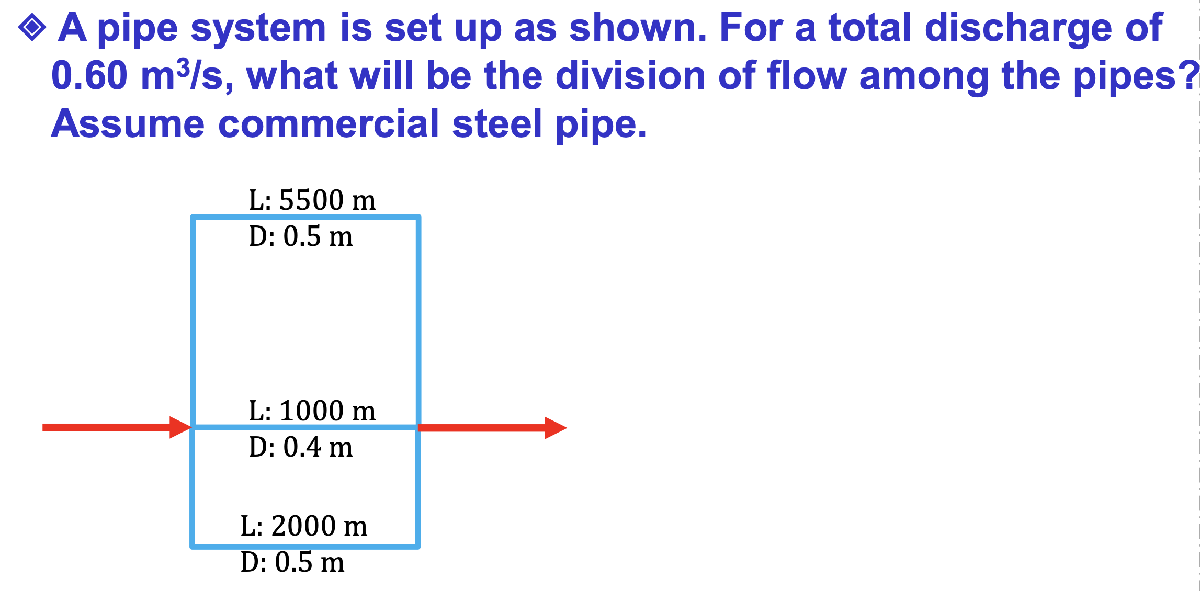

#### **set value**

Basic information

g = 9.81;
ccw = -1; %Counter clock wise

Kinemetic viscosty for Water ${20}^{\circ } C$

nu = 1 * 10^-6; %m

Commercial steel pipe for Sand-Graind Roughness, $k_s$

ks = 0.046 * 10^-3; %m

Total Discharge

Q = 0.6;

guess Q

Q1 = 0.2;
Q2 = 0.2;
Q3 = 0.2;

Pipe Information

L1 = 5500;
D1 = 0.5;
L2 = 1000;
D2 = 0.4;
L3 = 2000;
D3 = 0.5;

#### Basic Calculation

Area

A1 = pi * D1^2 / 4;
A2 = pi * D2^2 / 4;
A3 = pi * D3^2 / 4;

#### Find

for i = 1:200
    V1 = abs(Q1 / A1);
    V2 = abs(Q2 / A2);
    V3 = abs(Q3 / A3);

    Re1 = V1 * D1 / nu;
    Re2 = V2 * D2 / nu;
    Re3 = V3 * D3 / nu;

    f1 = 0.25 / (log10((ks/3.7/D1) + (5.74/(Re1^0.9))))^2;
    f2 = 0.25 / (log10((ks/3.7/D2) + (5.74/(Re2^0.9))))^2;
    f3 = 0.25 / (log10((ks/3.7/D3) + (5.74/(Re3^0.9))))^2;

    hf1 = f1 * L1 * V1^2 / D1 / 2 / g;
    hf2 = f2 * L2 * V2^2 / D2 / 2 / g;
    hf3 = f3 * L3 * V3^2 / D3 / 2 / g;

    x = 2;

    %Loop 1 
    hf_L1 = hf1 + ccw*hf2;
    hf_Q_L1 = hf1/Q1 + hf2/Q2;
    delta_L1 = - hf_L1 / hf_Q_L1 / x;

    %Loop 2
    hf_L2 = hf2 + ccw*hf3;
    hf_Q_L2 = hf2/Q2 + hf3/Q3;
    delta_L2 = - hf_L2 / hf_Q_L2 / x;

    %Correction
    Q1 = Q1 + delta_L1;
    Q2 = abs((ccw*Q2) + delta_L1 - delta_L2);
    Q3 = abs(ccw*Q3 + delta_L2);

     if (abs(delta_L1) + abs(delta_L2)) < 10^-3
        disp(['Re1 =  ', num2str(Re1, '%.4e')]);
        disp(['Re2 =  ', num2str(Re2, '%.4e')]);
        disp(['Delta1 =  ', num2str(delta_L1, '%.4e')]);
        disp(['Delta2 =  ', num2str(delta_L2, '%.4e')]);
        disp(['Q1 =  ', num2str(Q1, '%.4e')]);
        disp(['Q2 =  ', num2str(Q2, '%.4e')]);
        disp(['Q3 =  ', num2str(Q3, '%.4e')]);
        Q1 + Q2 + Q3
        break;
     end
end

Re1 =  3.7651e+05


Re2 =  6.4190e+05


Delta1 =  -4.7823e-04


Delta2 =  -4.9863e-04


Q1 =  1.4738e-01


Q2 =  2.0164e-01


Q3 =  2.5099e-01


ans = 0.6000